xmin = -1; xmax = 1;
ymin = -1; ymax = 1;
F = -1;

N = 128; M = (ymax-ymin)/(xmax-xmin)*N;
hx = (xmax-xmin)/N; hy = (ymax-ymin)/M;

gen_mesh_rectangle_bfs(N, M, xmin, xmax, ymin, ymax)

%% PDE data

% coefficient (a) of the equation
coef_a = 1.0;

% right-hand side function f (not implemented yet, constant for now)
fc_f = @(x) 1;

% Dirichlet data, function g_D
fc_gD = @(x) x(1)*0 + x(2)*0;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%  start  of  resolution
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if (exist('elem_vertices.txt', "file")==2)
    elem_vertices = load('elem_vertices.txt');
else
    disp('PANIC!  no  elem_vertices.txt  file');
    return
end
if (exist('vertex_coordinates.txt', "file")==2)
    vertex_coordinates   = load('vertex_coordinates.txt');
else
    disp('PANIC!  no  vertex_coordinates.txt  file');
    return
end

if (exist('dirichlet.txt', "file")==2)
    dirichlet  = load('dirichlet.txt');
else
    dirichlet = [];
end

if (exist('interior.txt', "file")==2)
    interior  = load('interior.txt');
else
    interior = [];
end

% end of mesh input


% Start of matrix and right-hand side asemmbly
n_vertices = size(vertex_coordinates, 1); 
n_elem = size(elem_vertices, 1);

A  = sparse(4*n_vertices, 4*n_vertices);
% the force is constant
fh = zeros(4*n_vertices, 1);
fh(1:4:end) = F*ones(n_vertices, 1);

% importing precomputed element matrix on the master element
master_el_mat = load('master_stiff_2d.mat').Kel2d;
el_area = hx*hy;

% [X,Y] = meshgrid(vertex_coordinates(:,1),vertex_coordinates(:,2));
% Z = zeros(n_vertices,n_vertices);
% surf(X,Y,Z)
% view([0 90])

tic;
for el = 1 : n_elem
    % computation of the element matrix
    el_mat = 1/el_area*coef_a*master_el_mat;
    
    v_elem = elem_vertices( el, : );
    
    v_elem_full = [4*v_elem(1)-3:4*v_elem(1) 4*v_elem(2)-3:4*v_elem(2) 4*v_elem(3)-3:4*v_elem(3) 4*v_elem(4)-3:4*v_elem(4)];
    
    % contributions added to the global matrix
    A( v_elem_full, v_elem_full ) = A( v_elem_full, v_elem_full ) + el_mat;
end
toc

Elapsed time is 132.732728 seconds.


fh = fh*el_area;
% save('stiffness_matrix_2d.mat','A');
% save('load_vector_2d.mat','fh');
% spy(A)

% only works for zero essential conditions, efficient

tic;
for i = 1:length(dirichlet)
    diri = dirichlet(i);
    
        if i == 1 || i == N+1 || i == N+1+M || i==N+1+M+N 
            % corners 
            % only u is prescribed
            diri_full = [4*diri-3];
            numcond = 1;
        elseif (i > 1 && i < N+1) || (i > N+1+M && i < N+1+M+N)
            % bottom and top walls
            % u and u_y prescribed
            diri_full = [4*diri-3 4*diri-1];
            numcond = 2;
        else 
            % left and right walls
            % u and u_x prescribed
            diri_full = [4*diri-3 4*diri-2];
            numcond = 2;
        end
    
    
    % replace rows and columns with canonical vectors
    A(diri_full,:) = zeros(numcond, 4*n_vertices);
    A(:,diri_full) = zeros(4*n_vertices, numcond);
    
    for j=1:numcond
        A(diri_full(j), diri_full(j)) = 1;
    end  
    fh(diri_full) = fc_gD(vertex_coordinates(diri, :));
end
toc

Elapsed time is 14.297474 seconds.


save('stiffness_matrix_2d.mat','A');
save('load_vector_2d.mat','fh');

% spy(A)
tic;
condest(A)

ans =      4.334090054820152e+07


toc

Elapsed time is 2.026586 seconds.


% solve for u
tic;
uh = A \ fh;
toc

Elapsed time is 0.343278 seconds.


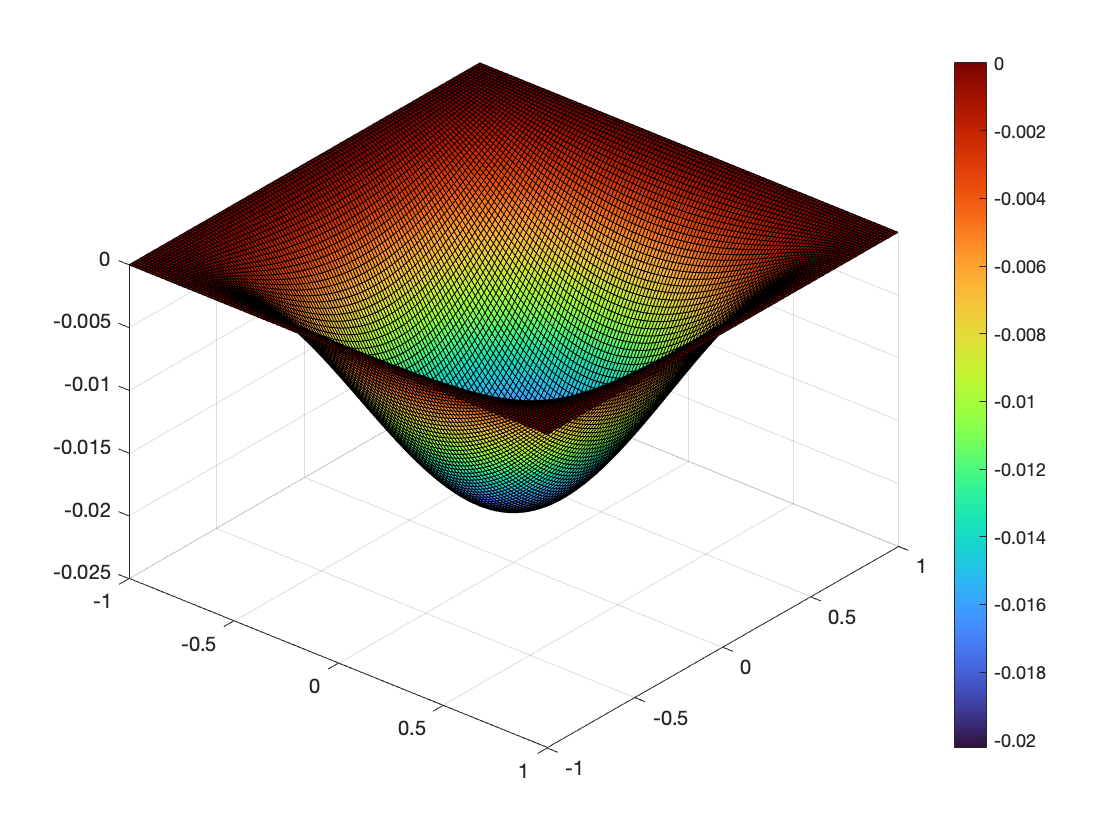

xdim = N+1;
ydim = M+1;
Uh = zeros(xdim, ydim);

for i=1:ydim
    for j=1:xdim
        n1 = (i-1)*(xdim) + (j-1) + 1;
        n = 4*n1-3;
        Uh(j,i) = uh(n);
    end
end

xs = linspace(xmin,xmax,xdim);
ys = linspace(ymin,ymax,ydim);

[X,Y] = meshgrid(xs,ys);
surf(X,Y,Uh')
zlim([min(0, 0.025*F) max(0,0.025*F)])
colormap turbo
colorbar
view([40 40])

## References

Implementing Dirichlet b.c.: [https://scicomp.stackexchange.com/questions/20515/how-to-efficiently-implement-dirichlet-boundary-conditions-in-global-sparse-fini](https://scicomp.stackexchange.com/questions/20515/how-to-efficiently-implement-dirichlet-boundary-conditions-in-global-sparse-fini) 

On BFS element: [https://arxiv.org/pdf/1905.09118.pdf](https://arxiv.org/pdf/1905.09118.pdf) 

Implementation of fixed mesh FEM: *Lecture slides by Pedro Morin*

**Preconditioners**:

- [http://www.math.iit.edu/~fass/477577_Chapter_16.pdf](http://www.math.iit.edu/~fass/477577_Chapter_16.pdf)  

- [https://scicomp.stackexchange.com/questions/1129/what-guidelines-should-i-use-when-searching-for-good-preconditioning-methods-for](https://scicomp.stackexchange.com/questions/1129/what-guidelines-should-i-use-when-searching-for-good-preconditioning-methods-for) 

- [http://people.maths.ox.ac.uk/wathen/preconditioning.pdf](http://people.maths.ox.ac.uk/wathen/preconditioning.pdf) 

- [http://www.mathcs.emory.edu/~benzi/Web_papers/survey.pdf](http://www.mathcs.emory.edu/~benzi/Web_papers/survey.pdf) 

- [https://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.92.3648&rep=rep1&type=pdf](https://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.92.3648&rep=rep1&type=pdf)* make matrix diag. dominant*

**Multigrid**:

- [https://ocw.mit.edu/courses/mathematics/18-086-mathematical-methods-for-engineers-ii-spring-2006/readings/am63.pdf](https://ocw.mit.edu/courses/mathematics/18-086-mathematical-methods-for-engineers-ii-spring-2006/readings/am63.pdf) 

- [https://www.math.tamu.edu/~bramble/psfiles/nmg4times.pdf](https://www.math.tamu.edu/~bramble/psfiles/nmg4times.pdf) 

- [https://arxiv.org/pdf/1802.00220.pdf](https://arxiv.org/pdf/1802.00220.pdf) 

- [**http://www.math.udel.edu/~szhang/research/p/1989a.pdf**](http://www.math.udel.edu/~szhang/research/p/1989a.pdf) 

- Ciarlet, P.G : The finite element method for elliptic problems. p. 76

- Bank, R., Dupont, T.: An optlmal order process for solving finite element equations.

- Hackbusch, W.: Multigrid methods and applications. Heidelberg, Berhn, New York: Springer 1985

- **Aitbayev **[**https://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.531.1830&rep=rep1&type=pdf**](https://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.531.1830&rep=rep1&type=pdf) 

- Deep multigrid: [https://arxiv.org/abs/1711.03825](https://arxiv.org/abs/1711.03825) 

- "Multigrid" by Trottenberg 

- FDM scheme for the biharmonic operator:  sciencedirect.com/topics/engineering/biharmonic-equation 

- Brenner, Multigrid for Biharmonic op. [https://epubs.siam.org/doi/pdf/10.1137/0726062](https://epubs.siam.org/doi/pdf/10.1137/0726062) 

- P-method and H-method by Babuska

- Suri & Arnold, Multigrid

- [https://www.sciencedirect.com/science/article/pii/S0377042700004118](https://www.sciencedirect.com/science/article/pii/S0377042700004118) 

- [http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.114.1088&rep=rep1&type=pdf](http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.114.1088&rep=rep1&type=pdf) Chebyshev smoother

**Sparse solvers**:

- Applied FEM Seigerlind.

- Nonlinear CG

[https://amses-journal.springeropen.com/articles/10.1186/s40323-020-00164-3](https://amses-journal.springeropen.com/articles/10.1186/s40323-020-00164-3) 